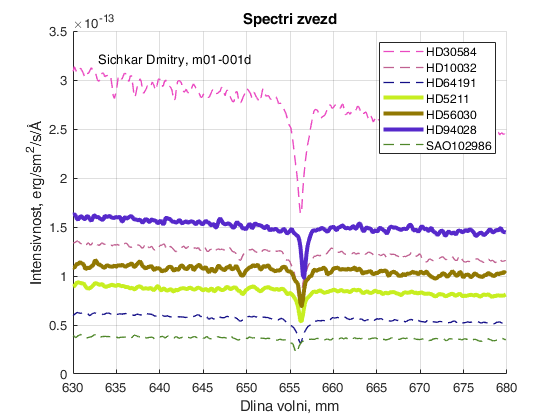

% Импортируйте данные из csv-файлов
starNames = importdata('star_names.csv');
spectra = importdata('spectra.csv');
lambdaStart = importdata('lambda_start.csv');
lambdaDelta = importdata('lambda_delta.csv');
% Определите константы
lambdaPr = 656.28; %нм
speedOfLight = 299792.458; %км/c
nStars = size(starNames,1 );
% Определите диапазон длин волн
nObs = size(spectra, 1);
lambdaEnd = lambdaStart + (nObs - 1) * lambdaDelta;
lambda = (lambdaStart : lambdaDelta : lambdaEnd)';
% Рассчитайте скорости звезд относительно Земли
for counter1 = 1 : nStars
s = spectra(:, counter1);
[sHa, idx] = min(s);
lambdaHa = lambda(idx);
z = (lambdaHa / lambdaPr) - 1; % Если z > 0 — красное смещение
speed(counter1) = z * speedOfLight;
end
speed = speed';
movaway = starNames(speed > 0);
% Постройте график
fg1 = figure;
hold on

for counter = 1 : nStars

s = spectra(:, counter);
[sHa, idx] = min(s);

lambdaHa = lambda(idx); % Длина волны с минимальной интенсивностью

if ( speed(counter) > 0 )
plot(lambda, s, 'LineWidth', 3, 'Color', [rand rand rand]);
end

if ( speed(counter) < 0 )
plot(lambda, s,'--', 'LineWidth', 1, 'Color', [rand rand rand]);
end

set(fg1, 'visible', 'on');

end
hold off
grid on

xlabel('Dlina volni, mm');
ylabel(['Intensivnost, erg/sm^2/s/', char(197)]);
title('Spectri zvezd');
legend(starNames);
text(lambdaEnd - 47, max(s)*8, ['Sichkar Dmitry, m01-001d'])
% Сохраните график
saveas(fg1, 'spectras.png')